# DOF-ProcSA/ParmSA-Result

# ParmSI 单个时间

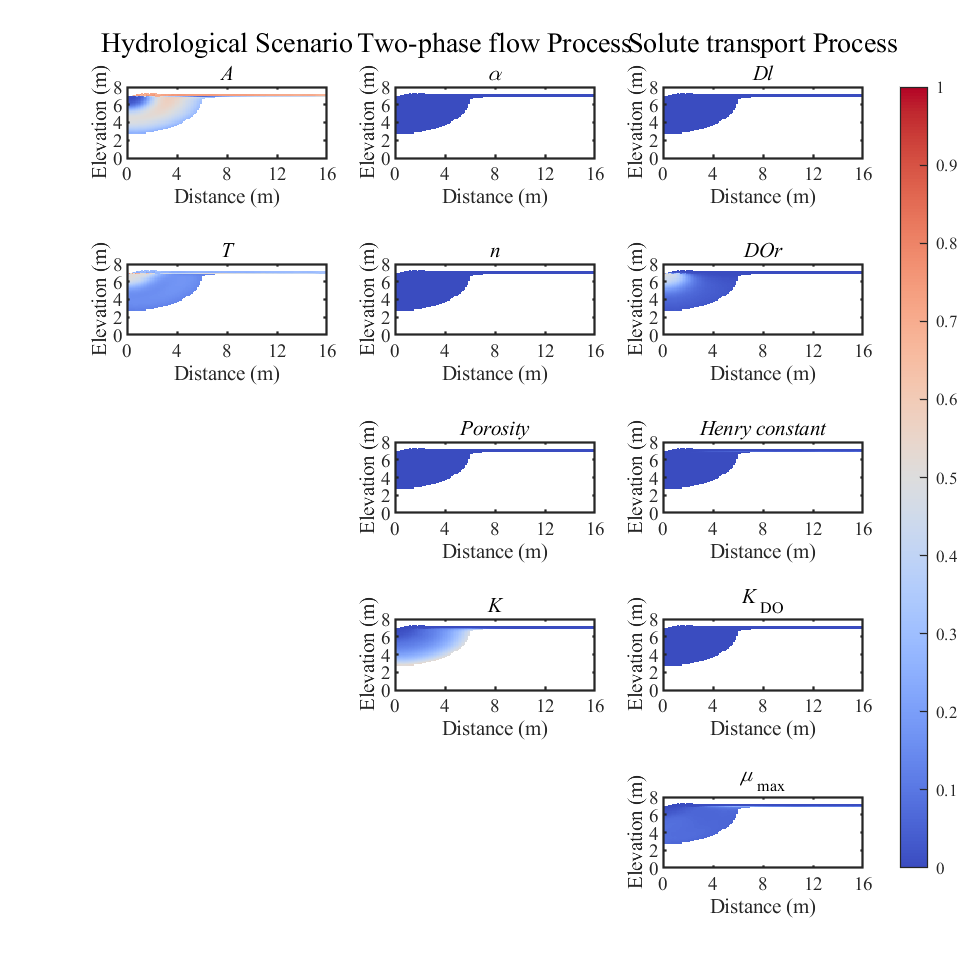

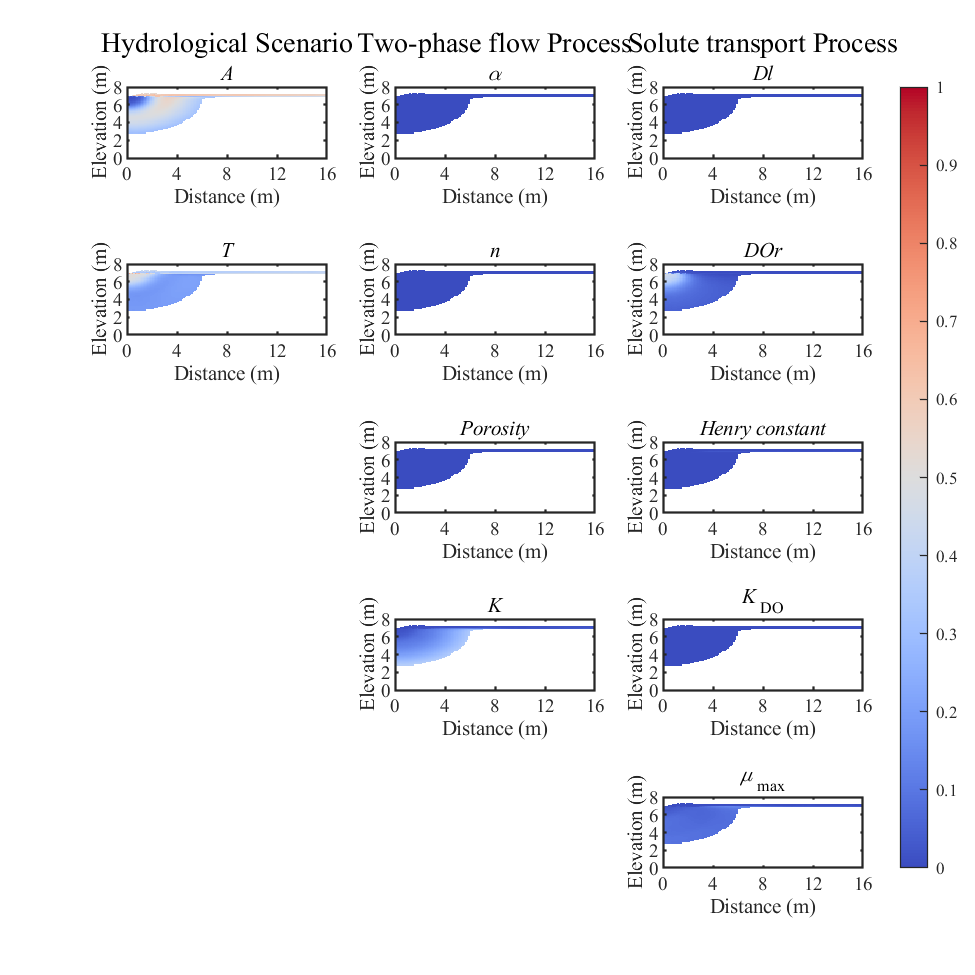

load("SI_Parm2d.mat")
load('Musk_2d.mat')
param = {'A' 'T' '\alpha' 'n' 'Porosity' 'K' 'Dl' 'DOr' 'Henry constant' 'K_{\rm DO}' '\mu_{\rm max}'};
proc = {'Hydrological Scenario', 'Two-phase flow Process', 'Solute transport Process'};
Musk_av(Musk_av==0) = nan;
SI1 = SI1_D(:,:,:,10);
SIT = SIT_D(:,:,:,10);
SI1 = SI1./sum(SI1,3);
SIT = SIT./sum(SIT,3);  % 归一化
id = [1 4 2 5 8 11 3 6 9 12 15];


% 一阶 总阶
for ff = 1:2

    if ff == 1
        f = figure; SI = SI1;
    else
        f1 = figure; SI = SIT;
    end

    tiledlayout(5,3);
    set(gcf,'position',[10 10 1000 1000])
    for i = 1:11
        nexttile(id(i))
        h = imagesc(SI(:,:,i).*Musk_av,'CDataMapping','scaled');
        colormap jet 
%         colormap(mymap("coolwarm")); % bwr coolwarm rainbow viridis
        set(h,'alphadata',~isnan(SI(:,:,i).*Musk_av))
        set(gca,'CLim',[0,1])
        ylabel({'Elevation (m)'});
        xlabel({'Distance (m)'});
        set(gca,'FontName','Times New Roman','Layer','top','LineWidth',1,...
            'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
            'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
            'YTick',[0.5 16.5 32.5 48.5 64.5],'YTickLabel',{'8','6','4','2','0'});

        if id(i) <=3
            [t,s] = title(proc(id(i)),param(i));
            t.FontSize = 12;s.FontAngle = 'italic';
        else
            title(param(i),'FontAngle','italic'); % ,'FontAngle','italic'
        end
    end
    cb = colorbar;
    cb.Layout.Tile = 'east';
    drawnow
end

# ProcSI 单个时间

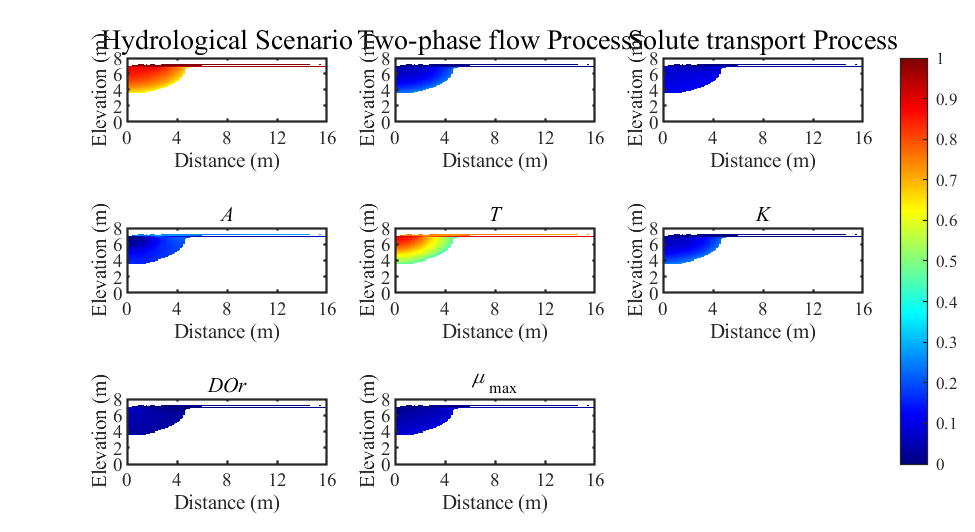

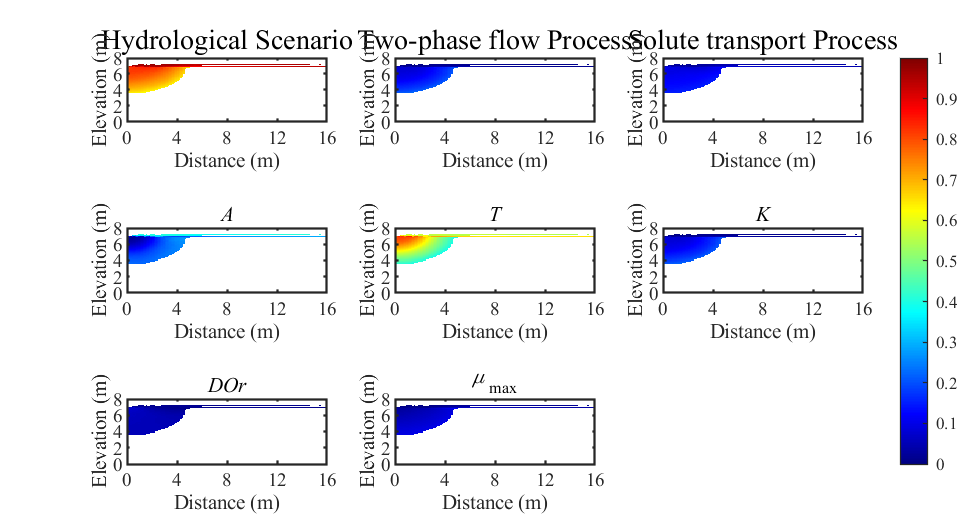

% load("SI_Proc.mat")
load("SI_Parm5d.mat")
load('Musk_5d.mat')

Title = {'Hydrological Scenario', 'Two-phase flow Process', 'Solute transport Process', ...
    'A', 'T', 'K', 'DOr', '\mu_{\rm max}'};
Musk_av(Musk_av==0) = nan;

SI = zeros(64,128,8);
% 一阶 总阶
for ff = 1:2

    if ff == 1
        f = figure; SI0 = SI1;
    else
        f1 = figure; SI0 = SIT;
    end
    SI(:,:,1) = sum(SI0(:,:,1:2),3);
    SI(:,:,2) = sum(SI0(:,:,3:6),3);
    SI(:,:,3) = sum(SI0(:,:,7:11),3);
    SI(:,:,4) = SI0(:,:,1);
    SI(:,:,5) = SI0(:,:,2);
    SI(:,:,6) = SI0(:,:,6); 
    SI(:,:,7) = SI0(:,:,8);
    SI(:,:,8) = SI0(:,:,11);
    SI = SI./sum(SI(:,:,1:3),3);

    tiledlayout(3,3);
    set(gcf,'position',[100 100 1100 600])
    for i = 1:8
        nexttile(i)
        if i<9
            h = imagesc(SI(:,:,i).*Musk_av,'CDataMapping','scaled');
            colormap jet % colormap(mymap("viridis"))
            set(h,'alphadata',~isnan(SI(:,:,i).*Musk_av))
            set(gca,'CLim',[0,1])
            ylabel({'Elevation (m)'});
            xlabel({'Distance (m)'});
            set(gca,'FontName','Times New Roman','Layer','top','LineWidth',1,...
                'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
                'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
                'YTick',[0.5 16.5 32.5 48.5 64.5],'YTickLabel',{'8','6','4','2','0'});

            if i <=3
                title(Title(i), 'FontSize', 12);
            else
                title(Title(i),'FontAngle','italic'); % ,'FontAngle','italic'
            end

        end
    end
    cb = colorbar;
    cb.Layout.Tile = 'east';
    drawnow
end

# 替代模型-拟合图

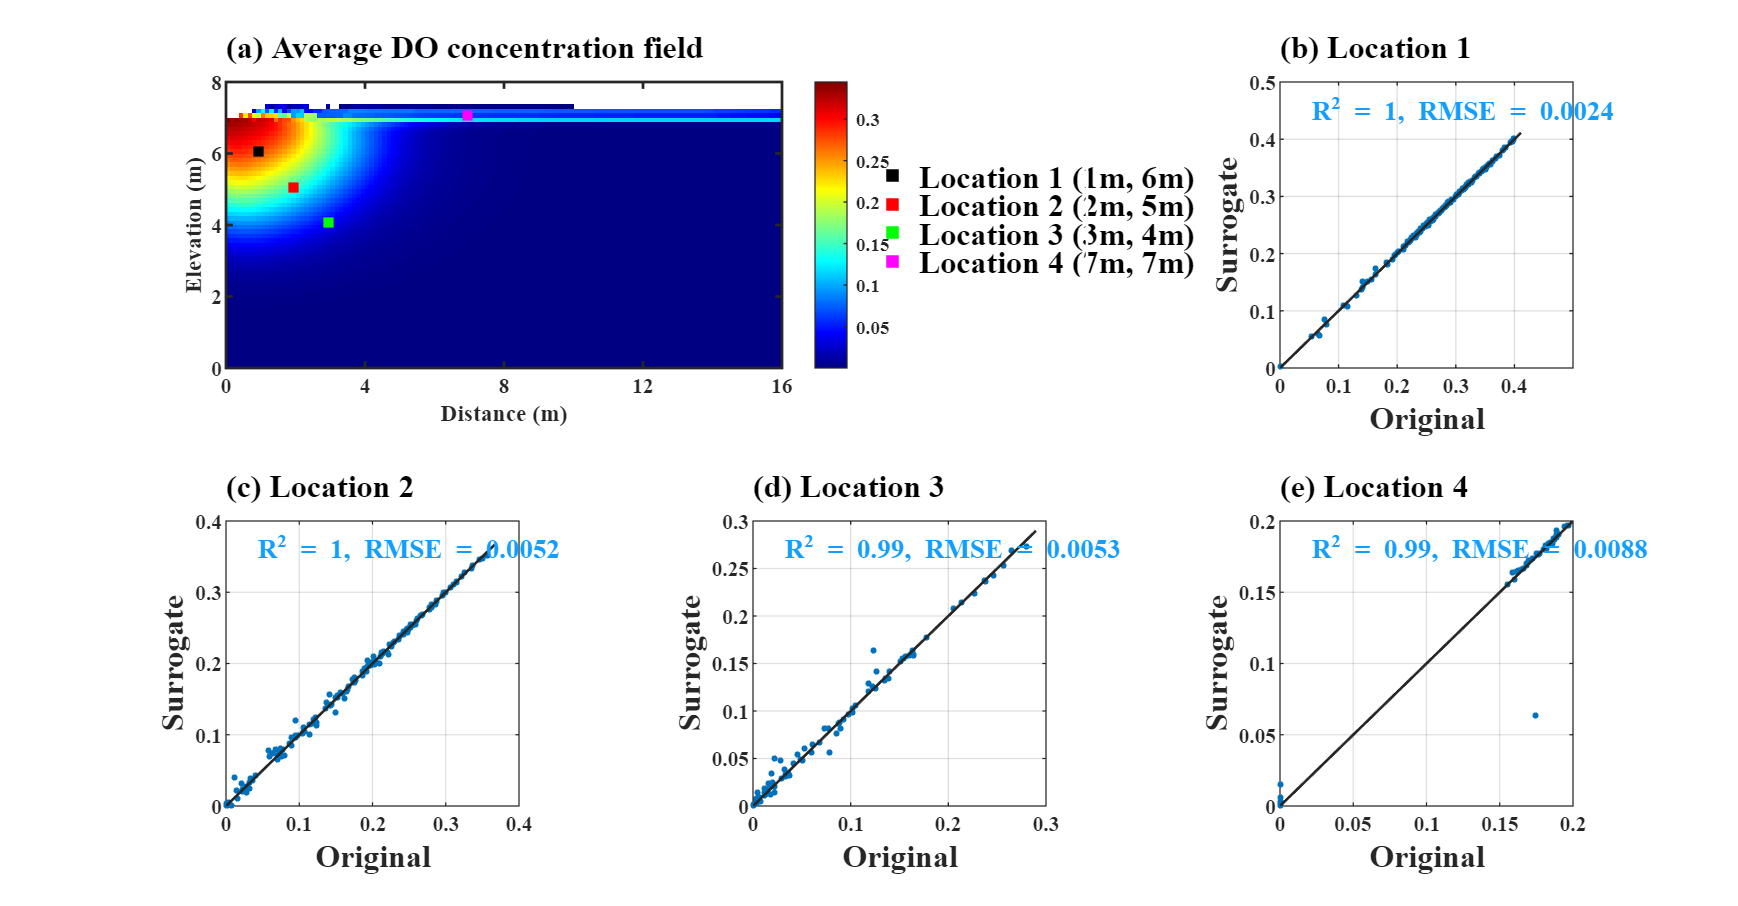

load('net2d.mat')

YPred = predict(net_cnn,TestX);
YPred=double(YPred);
YPred(YPred<0)=0;TestY(TestY<0)=0;

f = figure;
set(gcf,'position',[100 100 1150 600])
tiledlayout(2,6);
% Id = [16 8; 24 8; 16 24; 8 56];  % (1m, 6m) (1m, 5m) (3m, 6m) (7m, 7m)
Id = [16 8; 24 16; 32 24; 8 56]; % (1m, 6m) (2m, 5m) (3m, 4m) (7m, 7m)
% 绘制a图
nexttile(1,[1 3]);
img = squeeze(mean(TestY,4));
Musk_av = img;
Musk_av(img>0) = 1; Musk_av(Musk_av==0) = nan;
h = imagesc(img.*Musk_av,'CDataMapping','scaled');
set(h,'alphadata',~isnan(img.*Musk_av))
title('(a) Average DO concentration field', 'FontSize', 12,'FontWeight','bold');
colormap jet % colormap(mymap("viridis"))
colorbar
ylabel({'Elevation (m)'});
xlabel({'Distance (m)'});
set(gca,'FontName','Times New Roman','Layer','top','LineWidth',1,...
    'FontWeight','bold','TitleHorizontalAlignment','left',...
    'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
    'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
    'YTick',[0.5 16.5 32.5 48.5 64.5],'YTickLabel',{'8','6','4','2','0'});
hold on;

scatter(Id(1,2),Id(1,1),24,'k',"square",'filled','DisplayName','Location 1 (1m, 6m)');hold on % r
scatter(Id(2,2),Id(2,1),24,'r',"square",'filled','DisplayName','Location 2 (2m, 5m)');hold on
scatter(Id(3,2),Id(3,1),24,'g',"square",'filled','DisplayName','Location 3 (3m, 4m)');hold on 
scatter(Id(4,2),Id(4,1),24,'m',"square",'filled','DisplayName','Location 4 (7m, 7m)');hold on
legend1 = legend;
set(legend1,...
    'Position',[0.496869099031816 0.693293648068873 0.128291110658771 0.13107143272348],...
    'FontSize',12,...
    'EdgeColor',[1 1 1]);

% text(Id(1,2),Id(1,1),'▪ 1','Color','r');
% text(Id(2,2),Id(2,1),'▪ 2','Color','c');
% text(Id(3,2),Id(3,1),'▪ 3','Color','b');
% text(Id(4,2),Id(4,1),'▪ 4','Color','m');


% 绘制b、c、d、e图
Title = {'(b) Location 1', '(c) Location 2', '(d) Location 3', '(e) Location 4'};
for i = 1:4
    nexttile((i+1)*2+1, [1 2])
    x = squeeze(TestY(Id(i,1),Id(i,2),1,:));
    y = squeeze(YPred(Id(i,1),Id(i,2),1,:));
    [R2,R2_ad] = R_Squared(x,y);
    [RMSE,MEAN]= Rmse(x,y);

    scatter(x,y,48,'Marker','.');
    hold on;
    plot([0 max(max(x),max(y))+0.01], [0 max(max(x),max(y))+0.01], 'LineWidth',1, ...
    Color=[0.15 0.15 0.15]);
    
    grid on; box on;
    set(gca,'FontName','Times New Roman','TitleHorizontalAlignment','left','FontWeight','bold');
    title(Title(i), 'FontSize', 12,'FontWeight','bold')
    ylabel({'Surrogate'},'FontSize', 12);
    xlabel({'Original'},'FontSize', 12);
    if i == 1
        xlim(gca,[0 0.50]); ylim(gca,[0 0.50]);
        t=text(0.05,0.45,['R^2 = ' num2str(roundn(R2,-2)) ', RMSE = ' num2str(roundn(RMSE,-4))]);
    elseif i == 4
        xlim(gca,[0 0.2]); ylim(gca,[0 0.2]);
        t=text(0.02,0.18,['R^2 = ' num2str(roundn(R2,-2)) ', RMSE = ' num2str(roundn(RMSE,-4))]);
    elseif i == 2
        xlim(gca,[0 0.4]); ylim(gca,[0 0.4]);
        t=text(0.04,0.36,['R^2 = ' num2str(roundn(R2,-2)) ', RMSE = ' num2str(roundn(RMSE,-4))]);
    else
        xlim(gca,[0 0.3]); ylim(gca,[0 0.3]);
        t=text(0.03,0.27,['R^2 = ' num2str(roundn(R2,-2)) ', RMSE = ' num2str(roundn(RMSE,-4))]);
    end
    t.FontName = 'Times New Roman';t.FontWeight="bold"; t.Color = [0.07,0.62,1.00];

end

# 替代模型-多图展示

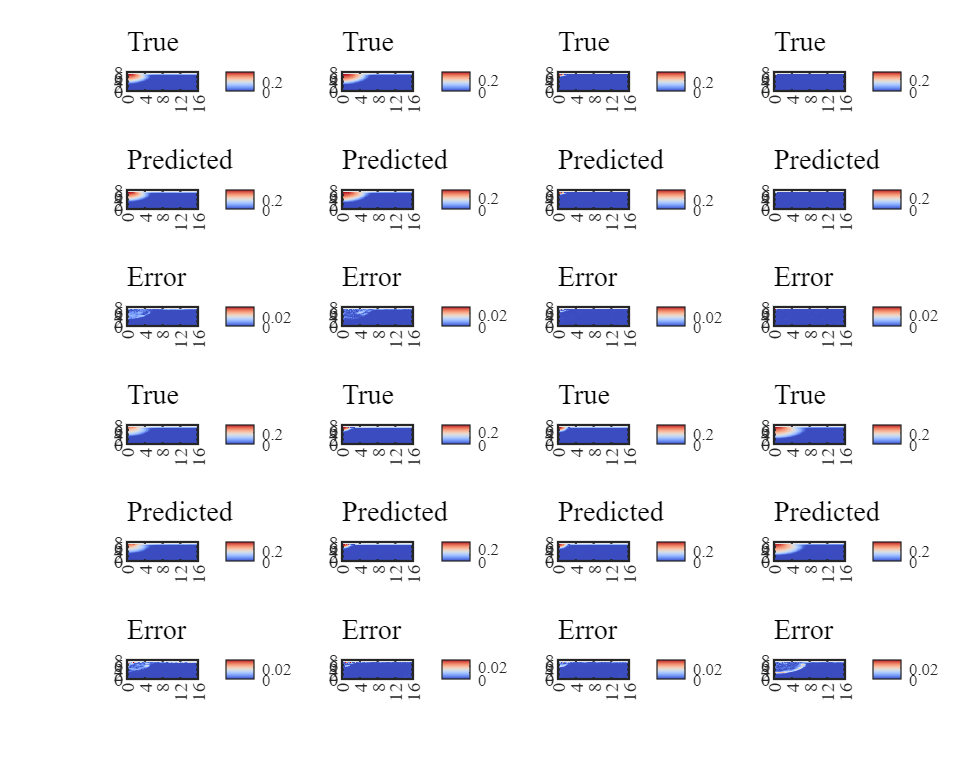

load('net7d.mat')

YPred = predict(net_cnn,TestX);
YPred=double(YPred);
YPred(YPred<0)=0;TestY(TestY<0)=0;
Id = [1 2 5 7 10 12 15 31];
loc = [1 3 5 7 25 27 29 31];

f = figure;
set(gcf,'position',[100 100 1100 860])
tiledlayout(6,8);
for i1 = 1:8
    for i2 = 1:3
        if i2 == 1
            img = squeeze(TestY(:,:,:,Id(i1)));
            Title = 'True'; U = max(max(img));
            Musk_av = img;
            Musk_av(img>0) = 1; Musk_av(Musk_av==0) = nan;
            Musk_av(9:end,:) = 1;
            nexttile(loc(i1),[1,2]);
        elseif i2 == 2
            img = squeeze(YPred(:,:,:,Id(i1)));
            Title = 'Predicted';
            nexttile(loc(i1)+8,[1,2]);
        else
            img = squeeze(abs(TestY(:,:,:,Id(i1))-YPred(:,:,:,Id(i1))));
            Title = 'Error';
            nexttile(loc(i1)+16,[1,2]);
        end

        h = imagesc(img.*Musk_av,'CDataMapping','scaled');
        set(h,'alphadata',~isnan(img.*Musk_av))
        title(Title, 'FontSize', 12);
        set(gca,'FontName','Times New Roman','TitleHorizontalAlignment','left');
%         colormap jet 
        colormap(mymap("coolwarm")); % bwr coolwarm rainbow
        colorbar
%         if i1 == 1 || i1 == 5
%             ylabel({'Elevation (m)'});
%         end
%         if i2 == 3
%             xlabel({'Distance (m)'});
%         end

        set(gca,'FontName','Times New Roman','Layer','top','LineWidth',1,...
            'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
            'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
            'YTick',[0.5 16.5 32.5 48.5 64.5],'YTickLabel',{'8','6','4','2','0'});
        if i2 == 1 || i2 == 2
            set(gca,'CLim',[0,U])
        else
            set(gca,'CLim',[0,U/10])
        end
    end
end

# 替代模型-多图展示-多时间

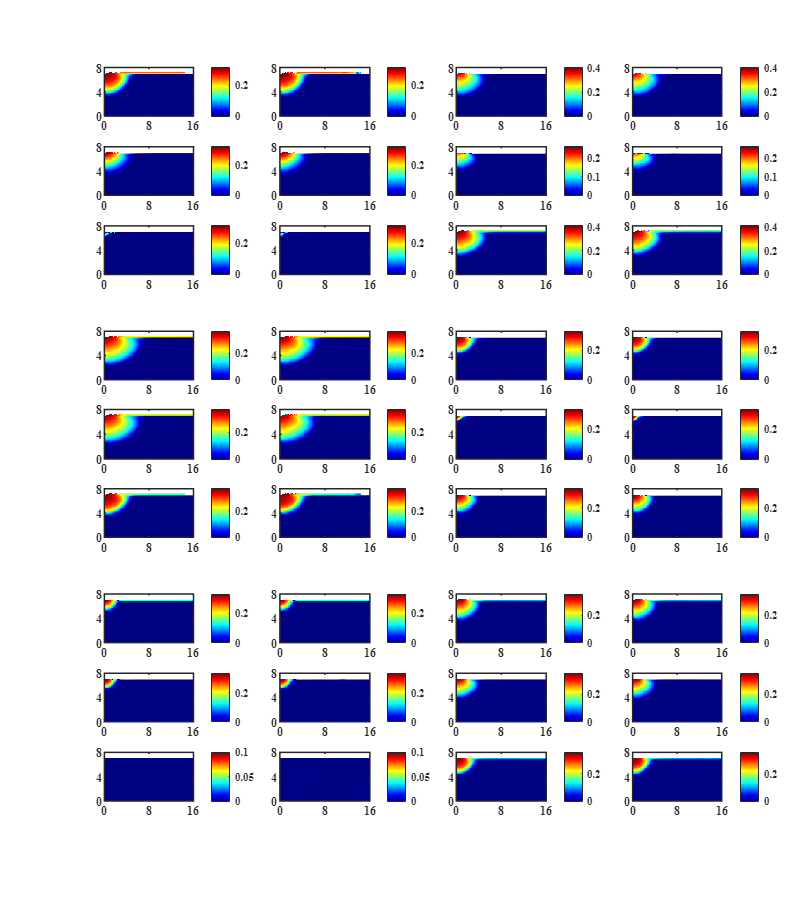

rng(999)
load('net2d.mat')
TestX0 = TestX;
Id = randperm(180,12);
% Id = Id(1,7:12);
XX = reshape(TestX0(:,:,:,Id),[11,12]);
% Id = [1 3 4 5 6 7];
loc = [1 3 41 43 81 83];

f = figure;
set(gcf,'position',[100 100 800 900])
t = tiledlayout(29,4);

for i1 = 1:3
    if i1 == 1
        load('net2d.mat')
    elseif i1 == 2
        load('net5d.mat')
    else
        load('net7d.mat')
    end
    YPred = predict(net_cnn,TestX0);
    YPred=double(YPred);
    YPred(YPred<0)=0;TestY(TestY<0)=0;

    for i2 = 1:6
        for i3 = 1:2
            if i3 == 1
                img = squeeze(TestY(:,:,:,Id(i2)));
                Title = 'True'; U = max(max(img));
                if U<0.01 
                    U =0.1;
                end
                Musk_av = img; Musk_av(img>0) = 1; 
                Musk_av(Musk_av==0) = nan; Musk_av(9:end,:) = 1;
                nexttile(loc(i2)+(i1-1)*12,[3,1]);
            else
                img = squeeze(YPred(:,:,:,Id(i2)));
                Title = 'Predicted';
                nexttile(loc(i2)+(i1-1)*12+1,[3,1]);
            end
            h = imagesc(img.*Musk_av,'CDataMapping','scaled');
            set(h,'alphadata',~isnan(img.*Musk_av))
%             if i1 == 1
%             title(Title, 'FontSize', 14,'FontWeight','bold');
%             end
%             set(gca,'FontName','Times New Roman','TitleHorizontalAlignment','center');
            colormap jet %colormap(mymap("coolwarm")); % bwr coolwarm rainbow
            cb = colorbar;

            set(gca,'CLim',[0,U],'FontName','Times New Roman',...
                'Layer','top','LineWidth',1,'FontWeight','bold',...
                'Xlim',[0.5 128.5],'XTick',[0.5  64.5  128.5],...
                'XTickLabel',{'0','8','16'}, 'Ylim',[0.5 64.5],...
                'YTick',[0.5  32.5  64.5],'YTickLabel',{'8','4','0'});

%             if (i2 == 1 || i2 == 4) && i3 == 1
%                 ylabel({'T = 2d'},'FontSize',14,'FontWeight','bold','Rotation',0);
%             end

        end
    end

end
t.TileSpacing = "compact";

# 替代模型-单个样本-单时间

rng(999)
Id = randperm(180,12);
load('net2d.mat')
TestX0 = TestX;
XX = reshape(TestX0(:,:,:,Id),[11,12]);
f = figure;
set(gcf,'position',[100 100 800 180])

i1 = 3;
if i1 == 1
    load('net2d.mat')
elseif i1 == 2
    load('net5d.mat')
else
    load('net7d.mat')
end
YPred = predict(net_cnn,TestX0);
YPred=double(YPred);
YPred(YPred<0)=0;TestY(TestY<0)=0;
t = tiledlayout(1,2);

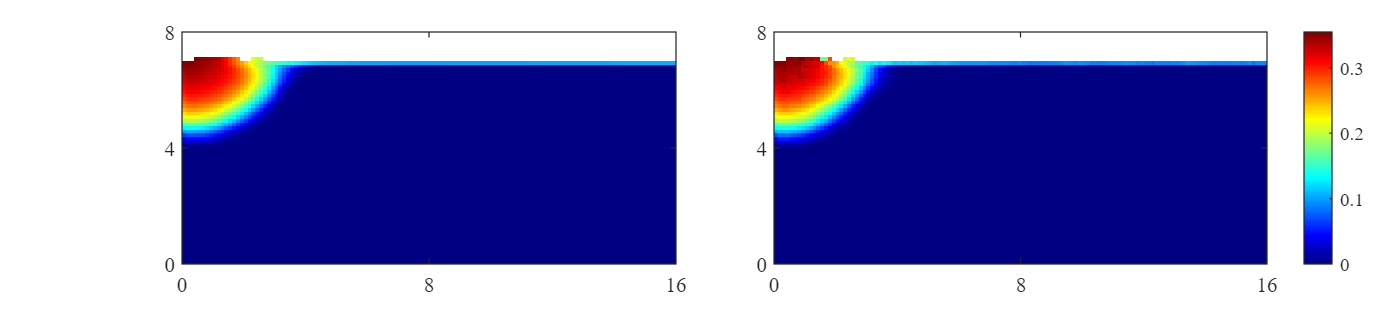

i2 = 6;
for i3 = 1:2
    if i3 == 1
        img = squeeze(TestY(:,:,:,Id(i2)));
        Title = 'True'; U = max(max(img));
        if U<0.01 
            U =0.1;
        end
        Musk_av = img; Musk_av(img>0) = 1; 
        Musk_av(Musk_av==0) = nan; Musk_av(9:end,:) = 1;
        nexttile(1)
    else
        img = squeeze(YPred(:,:,:,Id(i2)));
        Title = 'Predicted';
        nexttile(2)
    end

    h = imagesc(img.*Musk_av,'CDataMapping','scaled');
    set(h,'alphadata',~isnan(img.*Musk_av))
    colormap jet %colormap(mymap("coolwarm")); % bwr coolwarm rainbow
    if i3 == 2
        cb = colorbar;
    end

    set(gca,'CLim',[0,U],'FontName','Times New Roman',...
    'Layer','top','LineWidth',0.5,... %     'FontWeight','bold','FontSize', 8,...
    'Xlim',[0.5 128.5],'XTick',[0.5  64.5  128.5],...
    'XTickLabel',{'0','8','16'}, 'Ylim',[0.5 64.5],...
    'YTick',[0.5  32.5  64.5],'YTickLabel',{'8','4','0'});
end

t.TileSpacing = "compact";
cb.Layout.Tile = 'east';

# ParmSI \ ProcSI 饼图

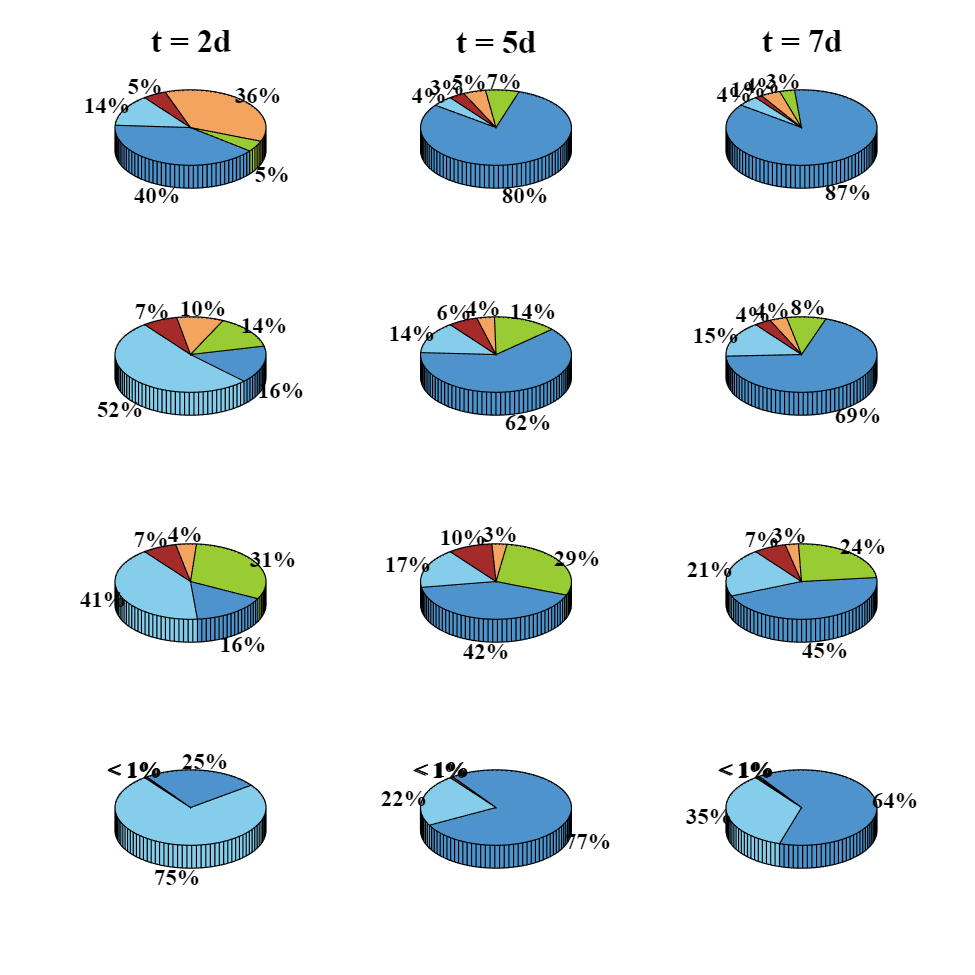

load('SIpoint.mat')
SI_Parm(:,:,[3:5 7 9 10]) = [];
SI_Parm = SI_Parm./sum(SI_Parm,3);
color = [0.52941 0.80784 0.92157
    0.3098	0.58039	0.80392   
    0.60392	0.80392	0.19608
    0.95686	0.64314	0.37647
    0.64706	0.16471	0.16471];
Title1 = {'\itA','\itT','\itK','\itDOr','\it\mu_{\rm\bf max}'};
Title2 = {'t = 2d', 't = 5d', 't = 7d'};
Title3 = {'Location 1', 'Location 2', 'Location 3', 'Location 4'};

figure
set(gcf,'position',[100 100 800 800])
colormap(color);
t = tiledlayout(4,3);
for i1 = 1:4
    for i2 = 1:3
        nexttile((i1-1)*3+i2);
        p = pie3(SI_Parm(i2,i1,:));
        for i3 = 1:5
            tt = p(i3*4);
            tt.FontSize = 10;
            tt.FontName = 'Times New Roman';
            tt.FontWeight = 'bold';
        end
        if i1 == 1
            title(Title2(i2),'FontSize',14,'FontWeight','bold','FontName','Times New Roman')
        end
        if i2 == 1
            ylabel(Title3(i1),'FontSize',14,'FontWeight','bold','FontName','Times New Roman');
        end
    end
end
% l = legend(Title1,'EdgeColor',[1 1 1]);
% l.Layout.Tile = "east";
t.TileSpacing = 'compact';
t.Padding = 'compact';

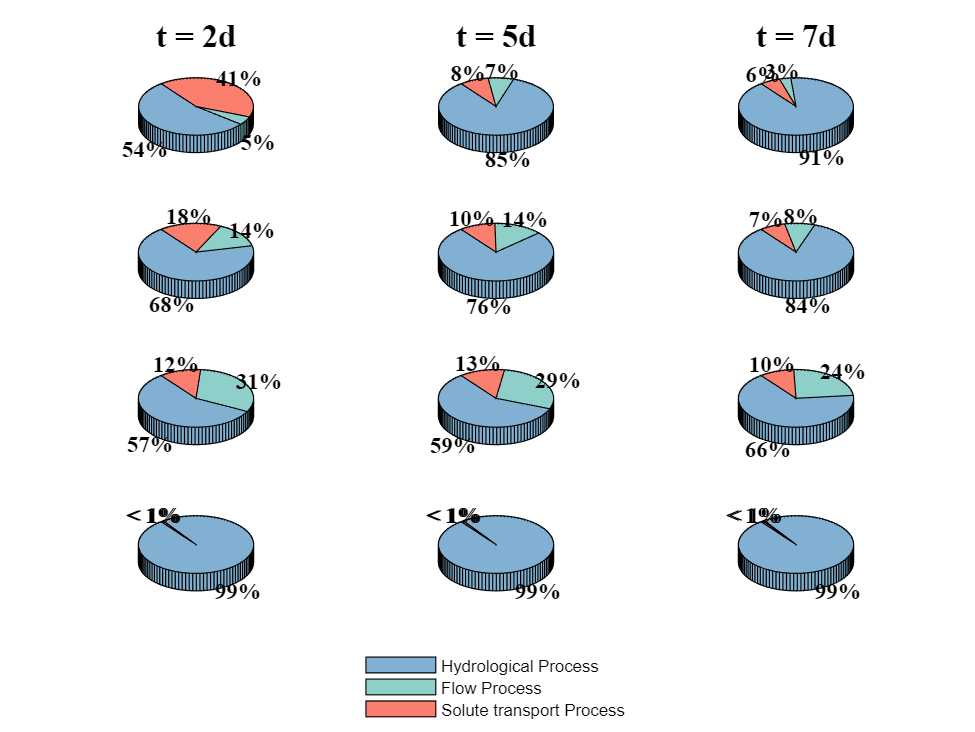

load('SIpoint.mat')
SI_Proc = SI_Proc./sum(SI_Proc,3);
color = [130,176,210;
    142,207,201;
    250,127,111]/255;
Title1 = {'Hydrological Process', 'Flow Process', 'Solute transport Process'};
Title2 = {'t = 2d', 't = 5d', 't = 7d'};
Title3 = {'Location 1', 'Location 2', 'Location 3', 'Location 4'};

figure
set(gcf,'position',[100 100 800 600])
colormap(color);
t = tiledlayout(4,3);
for i1 = 1:4
    for i2 = 1:3
        nexttile((i1-1)*3+i2);
        p = pie3(SI_Proc(i2,i1,:));
        for i3 = 1:3
            tt = p(i3*4);
            tt.FontSize = 10;
            tt.FontName = 'Times New Roman';
            tt.FontWeight = 'bold';
        end
        if i1 == 1
            title(Title2(i2),'FontSize',14,'FontWeight','bold','FontName','Times New Roman')
        end
        if i2 == 1
            ylabel(Title3(i1),'FontSize',14,'FontWeight','bold','FontName','Times New Roman');
        end
    end
end
l = legend(Title1,'EdgeColor',[1 1 1]);
l.Layout.Tile = "south";
t.TileSpacing = 'compact';
t.Padding = 'compact';

# ParmSI组图 多时间

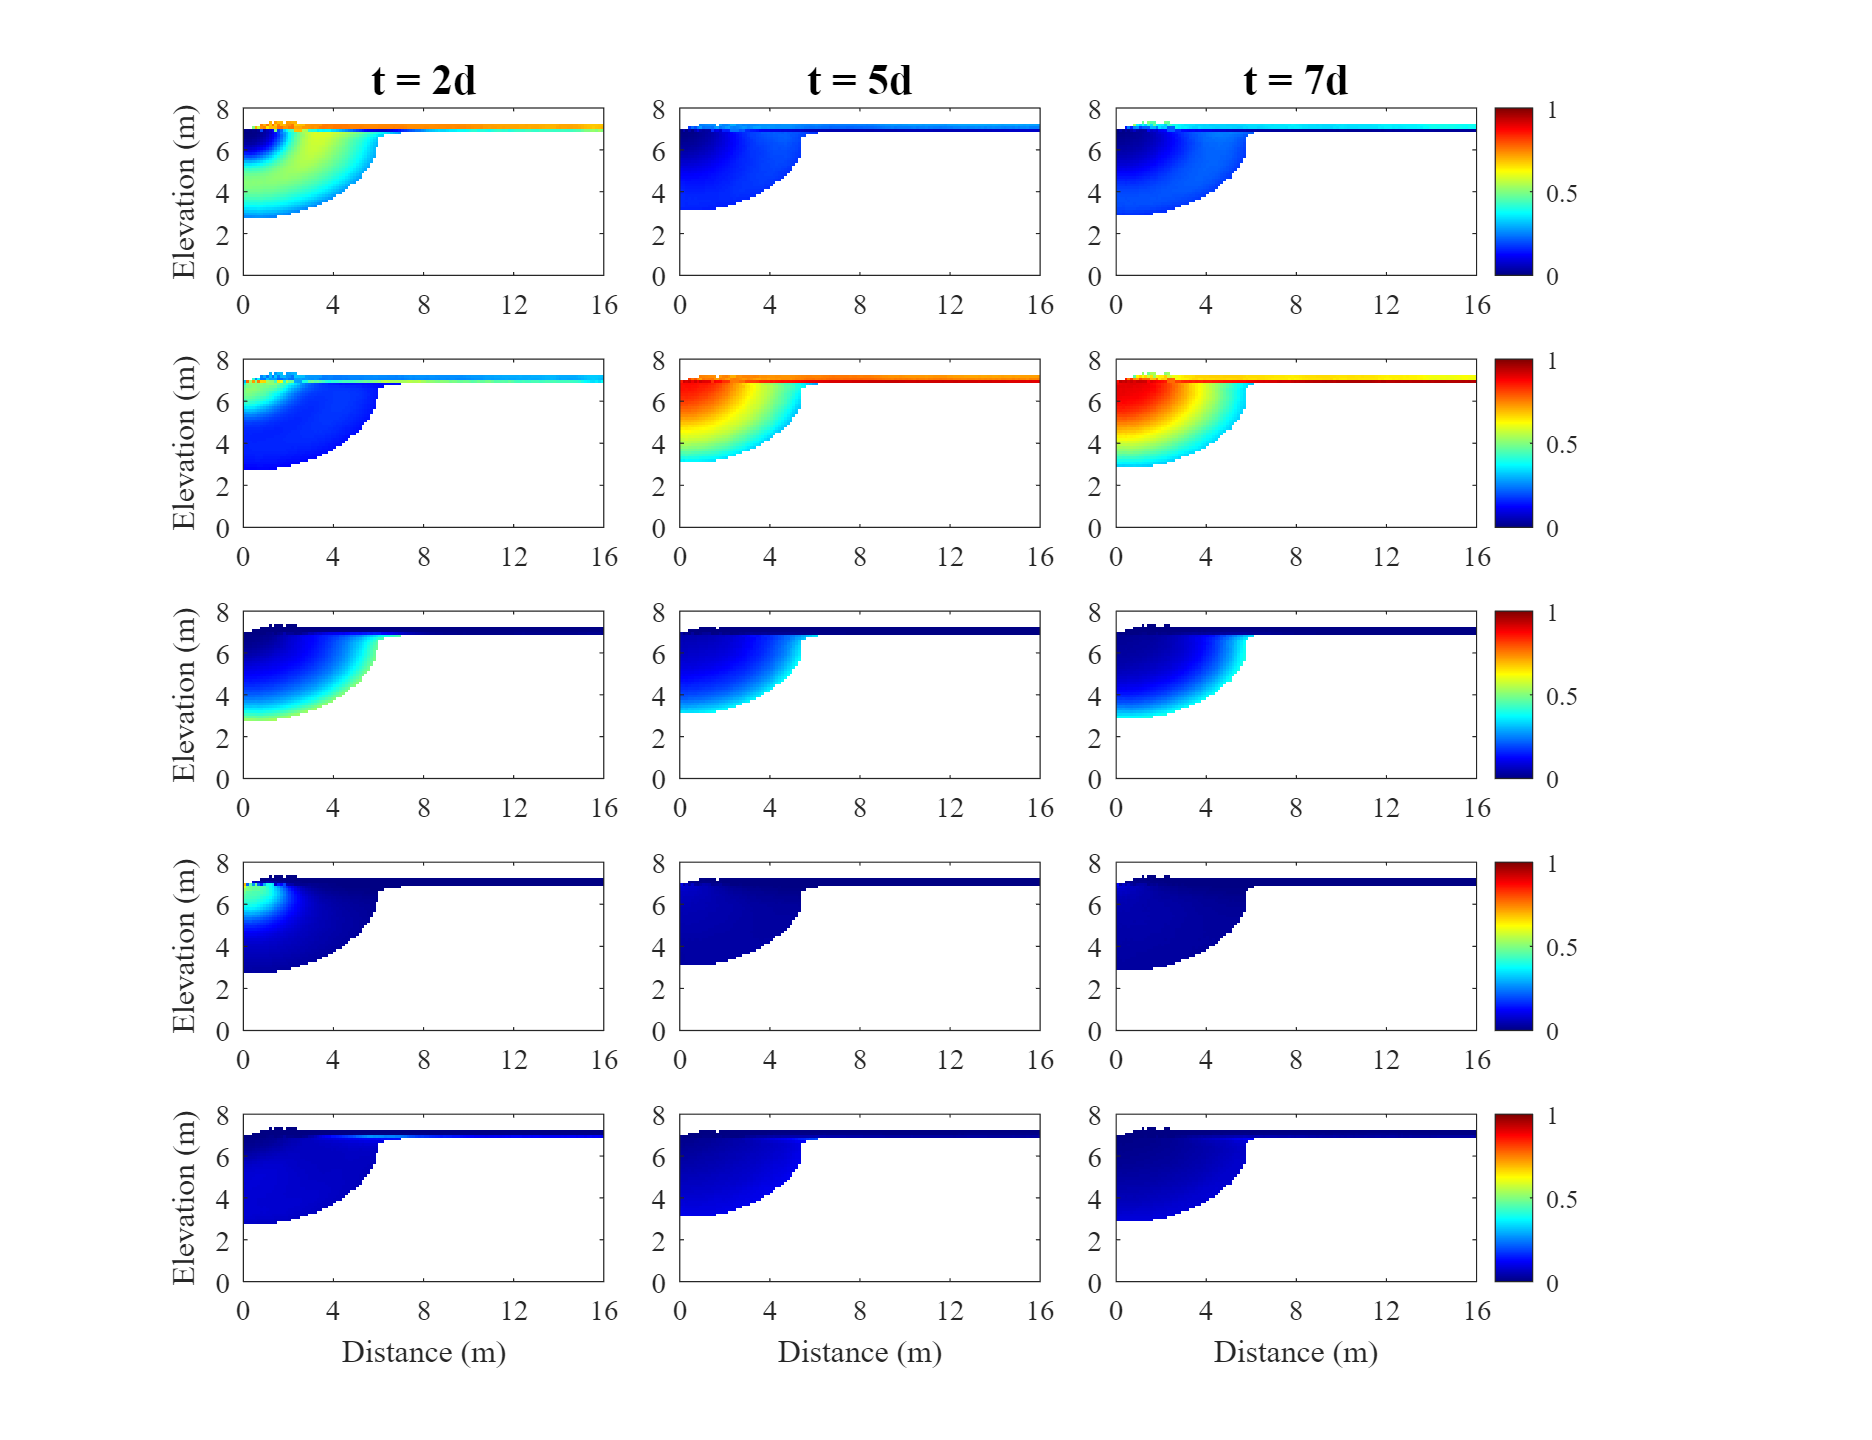

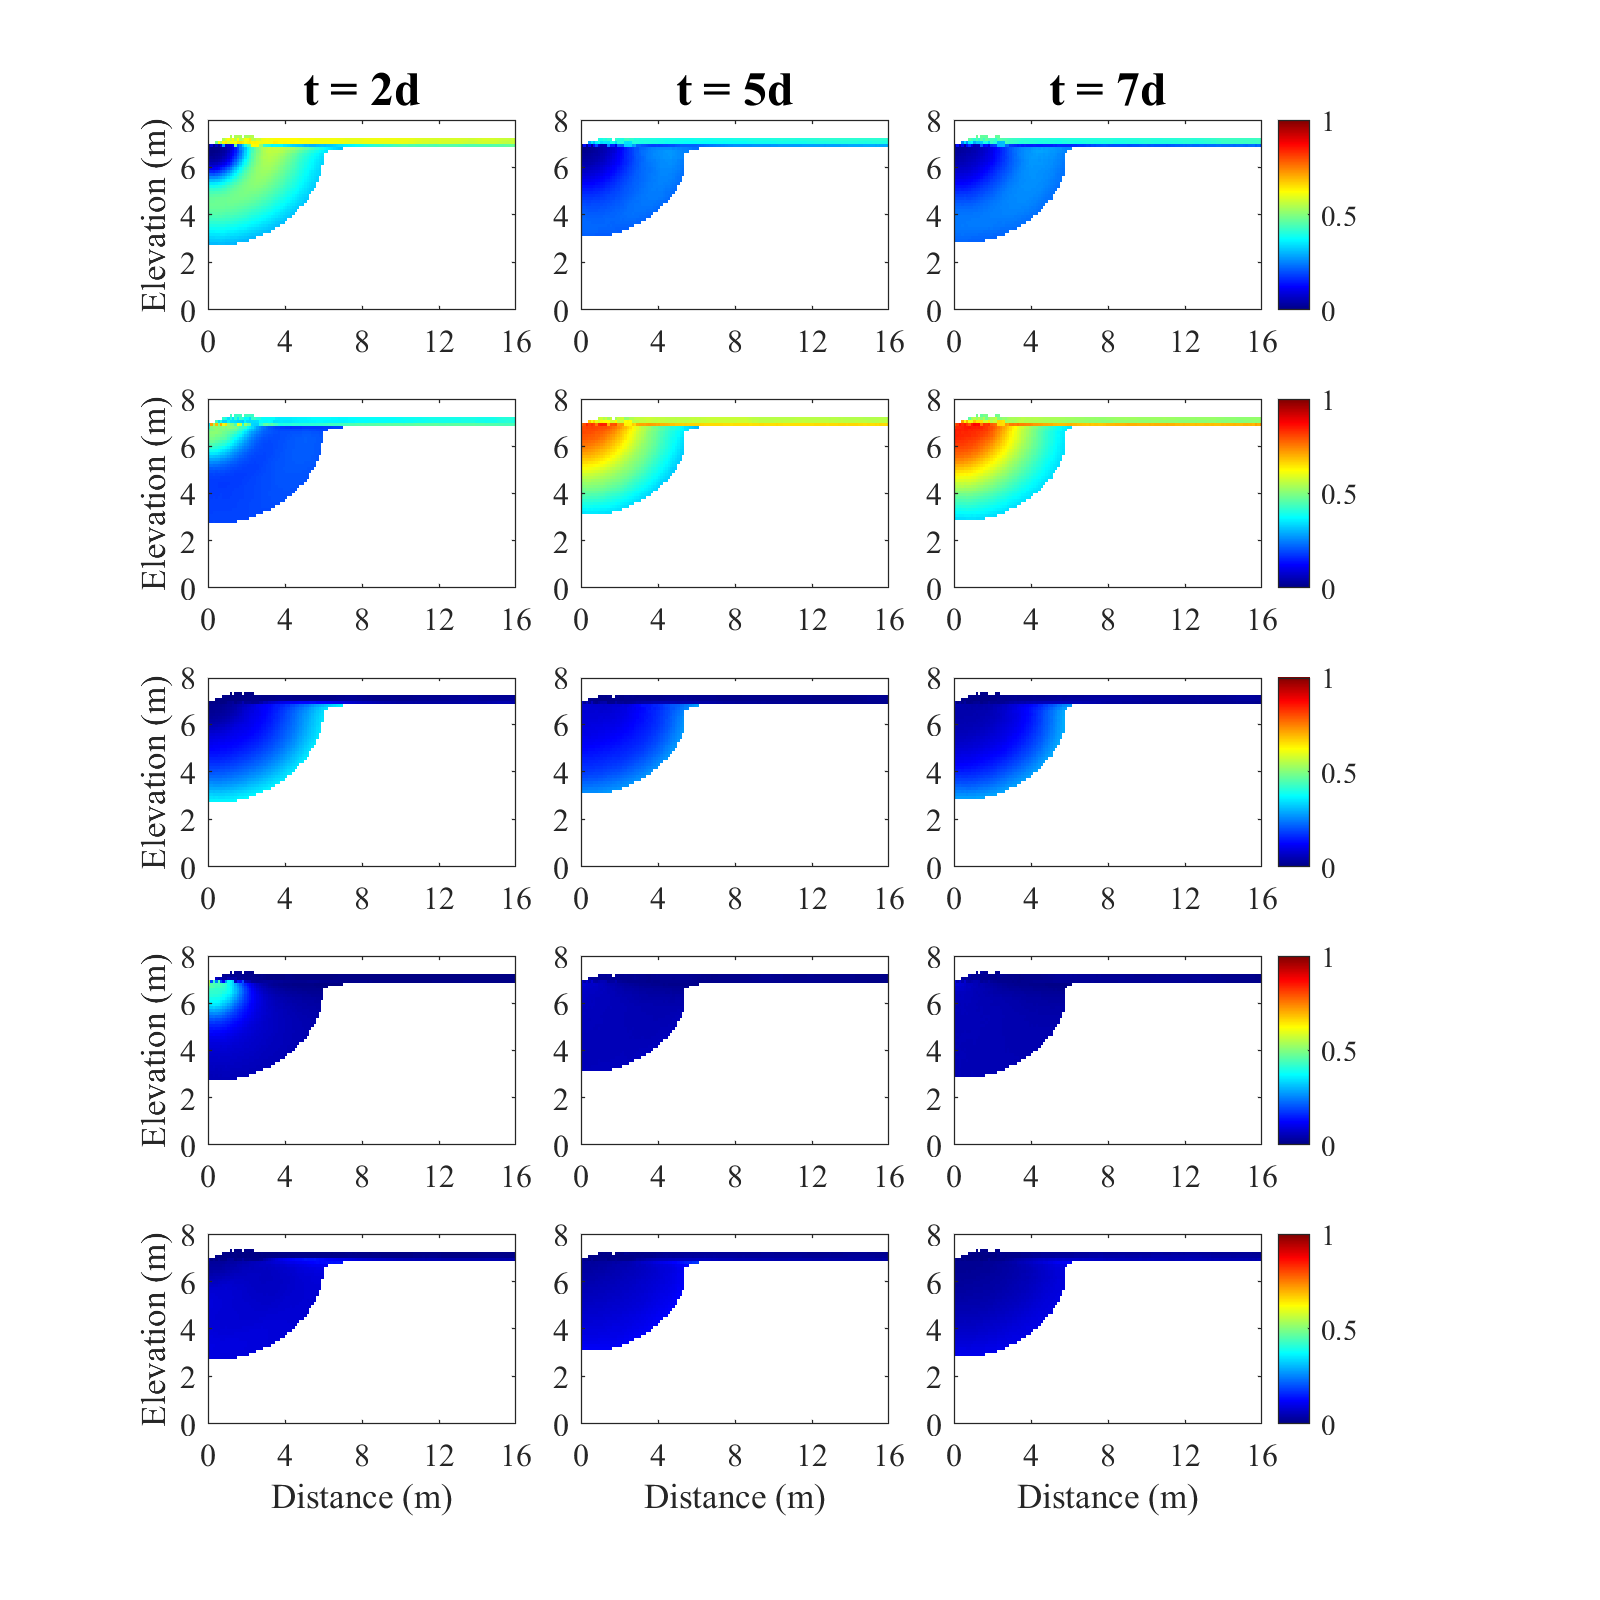

% Title1 = {'A' 'T' 'K' 'DOr' '\mu_{\rm max}'};
Title2 = {'t = 2d', 't = 5d', 't = 7d'};
id = [1 8 15 22 29];
U = [0 1; 0 1; 0 1; 0 1; 0 1];
% U = [0 0.6; 0.15 1; 0 0.6; 0 0.45; 0 0.3];


% 一阶 总阶
for ff = 1:2
    figure;
    tiledlayout(5,7);
    set(gcf,'position',[100 100 1300 1000])
    for i1 = 1:3
        if i1 == 1
            load("SI_Parm2d.mat");load('Musk_2d.mat');
        elseif i1 == 2
            load("SI_Parm5d.mat");load('Musk_5d.mat');
        else
            load("SI_Parm7d.mat");load('Musk_7d.mat');
        end

        if ff == 1
            SI0 = SI1;
        else
            SI0 = SIT;
        end

        Musk_av(Musk_av==0) = nan;
        SI = zeros(64,128,5);
        SI(:,:,1) = SI0(:,:,1);
        SI(:,:,2) = SI0(:,:,2);
        SI(:,:,3) = SI0(:,:,6);
        SI(:,:,4) = SI0(:,:,8);
        SI(:,:,5) = SI0(:,:,11);
        SI = SI./sum(SI,3);

        for i2 = 1:5
            nexttile(id(1,i2)+(i1-1)*2,[1,2])
            h = imagesc(SI(:,:,i2).*Musk_av,'CDataMapping','scaled');
            colormap jet
%             colormap(mymap("coolwarm")); % bwr coolwarm rainbow
            set(h,'alphadata',~isnan(SI(:,:,i2).*Musk_av))
            set(gca,'CLim',[U(i2,1),U(i2,2)])
            if i1 == 1
                ylabel({'Elevation (m)'});
            end
            if i2 == 5
                xlabel({'Distance (m)'});
            end
            set(gca,'FontName','Times New Roman','FontSize', 12,...
                'Layer','top','LineWidth',0.5,...
                'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
                'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
                'YTick',[0.5 16.5 32.5 48.5 64.5],...
                'YTickLabel',{'8','6','4','2','0'});
            if i1 == 1
                cb = colorbar;
                cb.Layout.Tile = i2*7;
            end
            if i2 == 1
                title(Title2(i1), 'FontSize', 18,'FontWeight','bold');
            end
        end
    end
end

# ProcSI组图 多时间

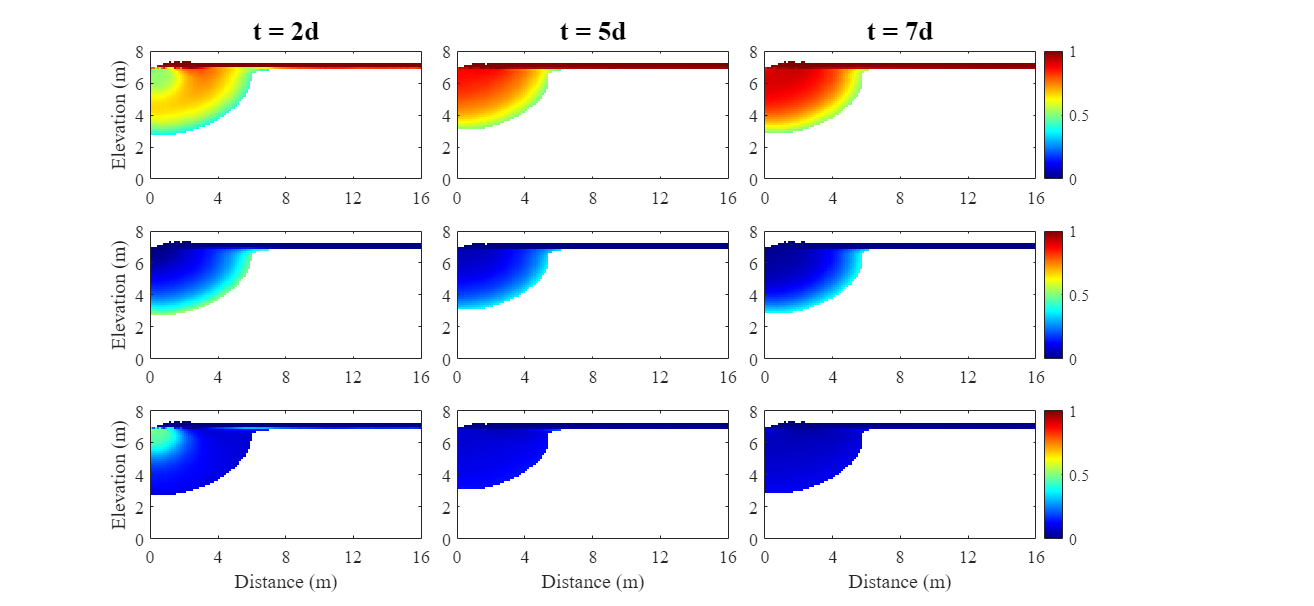

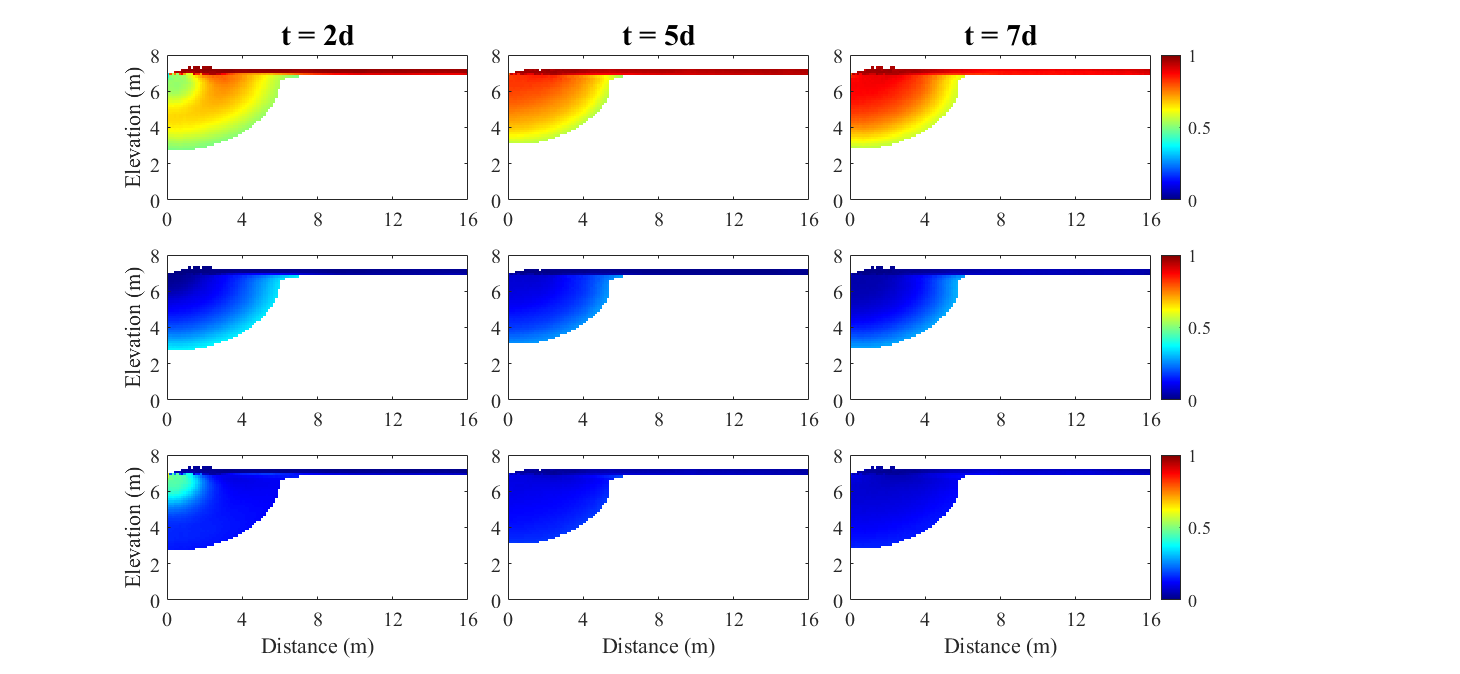

Title1 = {'S_{PH}', 'S_{PF}', 'S_{PR}'};
Title2 = {'t = 2d', 't = 5d', 't = 7d'};
id = [1 8 15; 3 10 17; 5 12 19; 7 14 21];
U = [0 1; 0 1; 0 1];
% U = [0.30 1; 0 0.60; 0 0.45];


% 一阶 总阶
for ff = 1:2
    figure;
    tiledlayout(3,7);
    set(gcf,'position',[100 100 1300 600])
    for i1 = 1:3
        if i1 == 1
            load("SI_Parm2d.mat");load('Musk_2d.mat');
        elseif i1 == 2
            load("SI_Parm5d.mat");load('Musk_5d.mat');
        else
            load("SI_Parm7d.mat");load('Musk_7d.mat');
        end

        if ff == 1
            SI0 = SI1;
        else
            SI0 = SIT;
        end

        Musk_av(Musk_av==0) = nan;
        SI = zeros(64,128,3);
        SI(:,:,1) = sum(SI0(:,:,1:2),3);
        SI(:,:,2) = sum(SI0(:,:,3:6),3);
        SI(:,:,3) = sum(SI0(:,:,7:11),3);   
        SI = SI./sum(SI(:,:,1:3),3);

        for i2 = 1:3
            nexttile(id(i1,i2),[1,2])
            h = imagesc(SI(:,:,i2).*Musk_av,'CDataMapping','scaled');
            colormap jet
%             colormap(mymap("coolwarm")); % bwr coolwarm rainbow
            set(h,'alphadata',~isnan(SI(:,:,i2).*Musk_av))
            set(gca,'CLim',[U(i2,1),U(i2,2)])
            if i1 == 1
                ylabel({'Elevation (m)'});
            end
            if i2 == 3
                xlabel({'Distance (m)'});
            end
            set(gca,'FontName','Times New Roman','FontSize', 12,...
                'Layer','top','LineWidth',0.5,...
                'Xlim',[0.5 128.5],'XTick',[0.5 32.5 64.5 96.5 128.5],...
                'XTickLabel',{'0','4','8','12','16'}, 'Ylim',[0.5 64.5],...
                'YTick',[0.5 16.5 32.5 48.5 64.5],...
                'YTickLabel',{'8','6','4','2','0'});
            if i1 == 1
                cb = colorbar;
                cb.Layout.Tile = id(4,i2);
            end
            if i2 == 1
                title(Title2(i1), 'FontSize', 18,'FontWeight','bold');
            end
        end
    end
end

# 函数

function [R2,R2_ad] = R_Squared(Y_actual,Y_predict)
Y_mean = mean(Y_actual);
TSS = sum((Y_actual-Y_mean).^2);
RSS = sum((Y_actual-Y_predict).^2);
R2 = 1-RSS/TSS;

n = size(Y_actual);
p = 11;
R2_ad = 1-(1-R2)*(n-1)/(n-p-1);
end

function [RMSE,MEAN ]= Rmse(Y_actual,Y_predict)
MEAN = mean(Y_actual);
RMSE = (mean((Y_actual-Y_predict).^2))^0.5;
end